% for a collection of timetables, plot data with uncertainty envelope
head(tt_aggr)

ans = 8×100 timetable
            Time            n1    n2    n3    n4    n5    n6    n7    n8    n9    n10    n11    n12    n13    n14    n15    n16    n17    n18    n19    n20    n21    n22    n23    n24    n25    n26    n27    n28    n29    n30    n31    n32    n33    n34    n35    n36    n37    n38    n39    

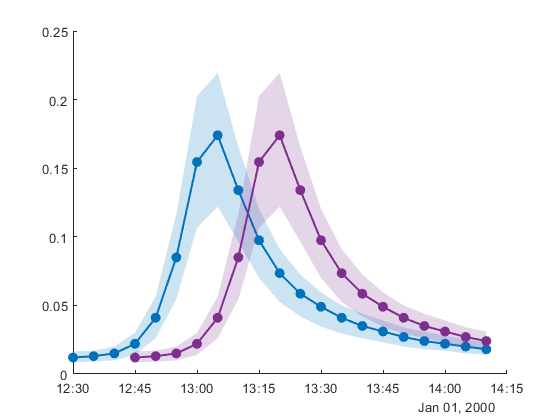

figure
plot_ue(tt_aggr(150:170,:));
plot_ue(lag(tt_aggr(150:170,:),hours(0.25)));

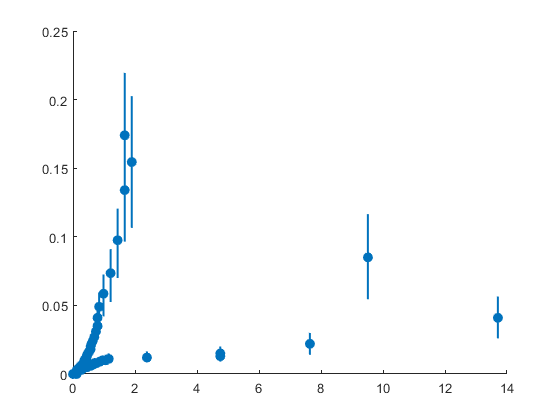

ans =   uncertainty_scatter with properties:

            MedPlot: [1×1 Line]
           MeanPlot: [1×1 Line]
    HorizontalLines: []
      VerticalLines: {1×288 cell}
         Percentile: 75
              Color: [0 0.4470 0.7410]
          LineWidth: 1.5000
           ShowMean: 0
         ShowMedian: 1


% similarly, plot scatterplot with uncertainty
figure
plot_us(tt_precip.Variables,tt_aggr.Variables)

% for single variable timetables, plot values against rowtimes; add units
% and variable names automatically
head(tt_outfl(:,'depth'))

ans = 8×1 timetable
            Time            depth
    ____________________    _____

    01-Jan-2000 00:05:00      0  
    01-Jan-2000 00:10:00      0  
    01-Jan-2000 00:15:00      0  
    01-Jan-2000 00:20:00      0  
    01-Jan-2000 00:25:00      0  
    01-Jan-2000 00:30:00      0  
    01-Jan-2000 00:35:00      0  
    01-Jan-2000 00:40:00      0  


head(tt_precip)

ans = 8×1 timetable
            Time            precip
    ____________________    ______

    01-Jan-2000 00:05:00      0   
    01-Jan-2000 00:10:00      0   
    01-Jan-2000 00:15:00      0   
    01-Jan-2000 00:20:00      0   
    01-Jan-2000 00:25:00      0   
    01-Jan-2000 00:30:00      0   
    01-Jan-2000 00:35:00      0   
    01-Jan-2000 00:40:00      0   


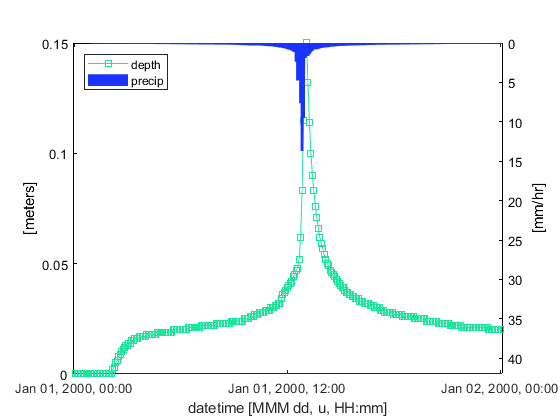

figure
plot_tt(tt_outfl(:,'depth'),'sq-','Color',[.1,.9,.6]);
hold on
plot_hy(tt_precip,'FaceColor',[.1,.2,1],'BarWidth',2);
legend('location','northwest');